# Demension Reduction with Synthetic Target Implantation (TI) and Target Embeddedness (TE) Datasets Using MATLAB

In this demo project, we will demostrate various techniques for dimension reduction in hyperspectral images with MATLAB.

## 1. Download the Dataset from Github and Loading the Dataset

Downloads the dataset by cloning the tite GitHub repository to the local environment. The dataset is stored in a folder named tite. Then, we can load the variables from the tite_reflectance.mat file into the MATLAB environment.

if ~exist("./tite/tite_reflectance.mat")
    gitclone("https://github.com/Brunoxue/tite.git");
end

load("tite/tite_reflectance.mat");
hsi=double(TE2);

## 2. Principal Component Analysis (PCA)

This block demonstrates how to apply Principal Component Analysis (PCA) for dimension reduction of a Hyperspectral Image (HSI) and visualize the results. After PCA, the data is visualized by showing the first 6 principal components as 2D images, which represent the main spectral variance in the original HSI data.

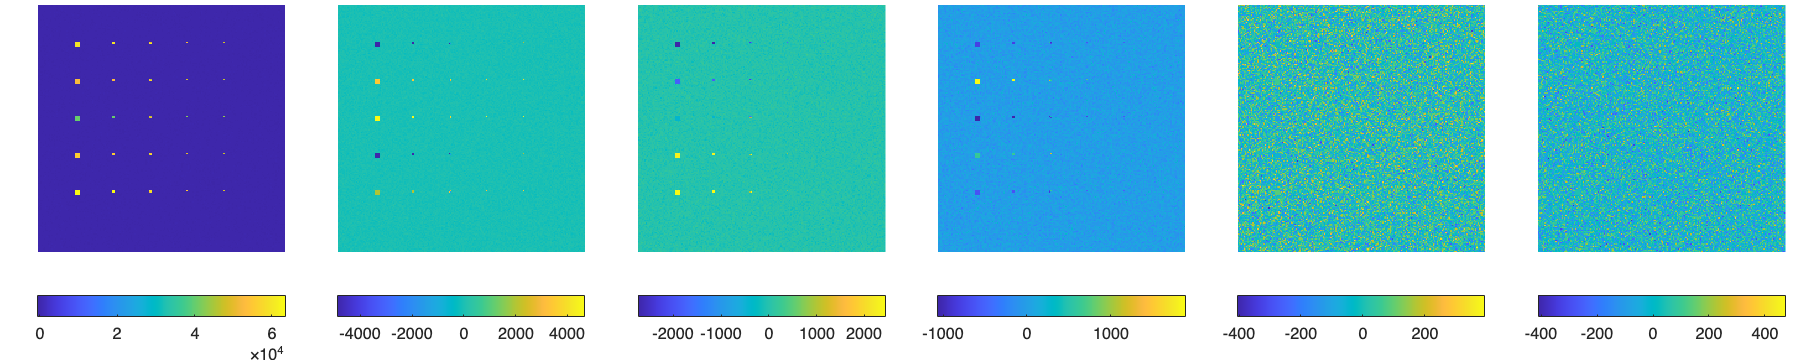

% Principal Component Analysis (PCA)
% Number of principal components to retain
nComp = 6;

% Get the size of the hyperspectral image (hsi)
% Reshape the hyperspectral data into a 2D matrix 
[x,y,L]=size(hsi);
N=x*y;
r=reshape(hsi,N,L);

% Apply PCA to the reshaped data
[~,PCAScore,~]=pca(r);

% Reshape the PCA result back to the original spatial dimensions
% Only the first nComp principal components are kept
PCAScore=reshape(PCAScore(:,1:nComp),x,y,nComp);

% Visualization
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,nComp,"TileSpacing","tight","Padding","tight");
for idx = 1:nComp
    nexttile,imagesc(PCAScore(:,:,idx)),axis off,axis image;
    colorbar southoutside;
end

## 3. Maximum Noise Fraction (MNF)

This block  demonstrates how to apply the Maximum Noise Fraction (MNF) transform to reduce the spectral dimension of a Hyperspectral Image (HSI) and visualize the results. MNF is useful for separating signal from noise and improving data quality. Noise is estimated by calculating the differences between consecutive pixels in the HSI data along the spatial dimension (Green et. al, 1988).

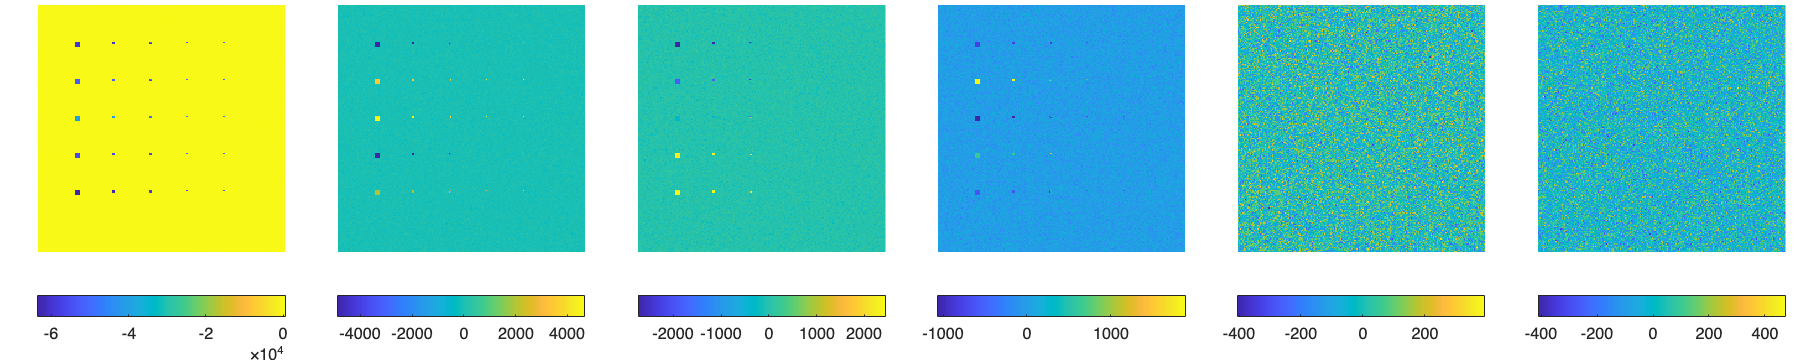

% Maximum Noise Fraction (MNF)
% Number of components to retain
nComp = 6;

% Apply MNF to the HSI data
% The function of MNF can be found in the bottom
[hsi_mnf] = MNF(hsi);

% Only the first nComp principal components are kept
hsi_mnf = hsi_mnf(:,:,1:nComp);

% Visualization
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,nComp,"TileSpacing","tight","Padding","tight");
for idx = 1:nComp
    nexttile,imagesc(hsi_mnf(:,:,idx)),axis off,axis image;
    colorbar southoutside;
end

## 4. Non-negative Matrix Factorization (NMF)

This block applies NMF to reduce the spectral dimensionality of hyperspectral data while ensuring that the resulting components are non-negative. NMF is utilized for the dimensionality reduction purpose that decomposes the data into non-negative factors. It is especially useful for data with natural non-negativity constraints.

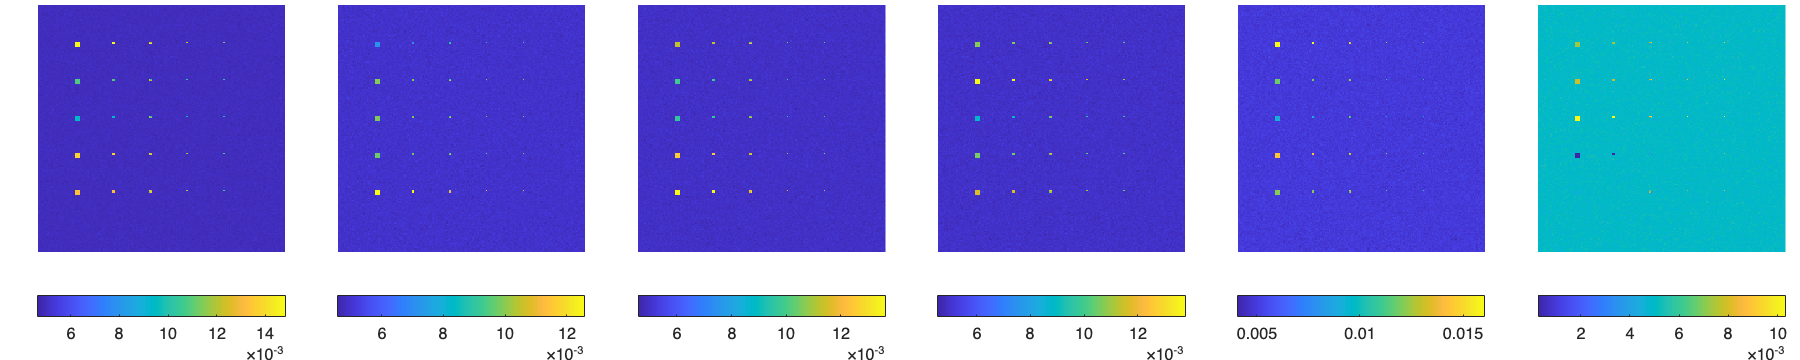

% Nonnegative Matrix Factorization (NMF)
% Number of components to retain
nComp=6;

% Get the size of the hyperspectral image (hsi)
% Reshape the hyperspectral data into a 2D matrix 
[x,y,L]=size(hsi);
N=x*y;
r=reshape(hsi,N,L);

% Apply NMF to the reshaped data
[~,NMFResult] = nnmf(r',nComp);

% Reshape the PCA result back to the original spatial dimensions
NMFResult=reshape(NMFResult',x,y,nComp);

% Visualization
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,6,"TileSpacing","tight","Padding","tight");
for idx = 1:6
    nexttile,imagesc(NMFResult(:,:,idx)),axis off,axis image;
    colorbar southoutside;
end

## Functions for Above Tasks


% Functions
function [hsi_mnf]=MNF(HSI)
    [x,y,L] = size(HSI);
    N=x*y;
    
    r=reshape(HSI,N,L);
    u=mean(r,1);
    r=r-repmat(u,N,1);
    
    noise_fraction=diff(reshape(r,x,y,L));
    [x_n,y_n,L] = size(noise_fraction);
    N_n=x_n*y_n;
    
    r_n=reshape(noise_fraction,N_n,L);
    nR=r_n'*r_n/N_n;
    
    % [V, D]=eig(nR);
    [V, ~, ~] = svd(nR, 'econ');
    
    [~,results,~]=pca(r*V,"Centered","off");
    
    hsi_mnf=reshape(results,x,y,L);
end